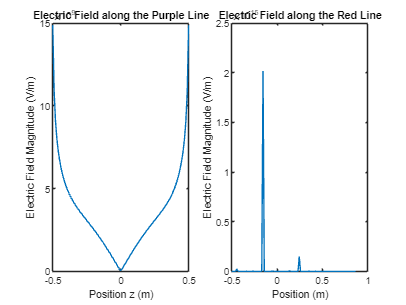

% Define constants
rho = 0.1; % Charge density in C/m^3
a = 1; % Edge length of the cube in meters
epsilon_0 = 8.854187817e-12; % Vacuum permittivity in F/m

% Calculate electric field along the purple and red lines
purple_line = linspace(-a/2, a/2, 100);
red_line = linspace(-a/2, sqrt(3)*a/2, 100);
E_purple = zeros(100, 3); % Initialize array to hold electric field values
E_red = zeros(100, 3); % Initialize array to hold electric field values

% Calculate fields for purple line
for idx = 1:length(purple_line)
    E_purple(idx, :) = electric_field(0, 0, purple_line(idx), rho, a, epsilon_0);
end

% Calculate fields for red line
for idx = 1:length(red_line)
    E_red(idx, :) = electric_field(red_line(idx), red_line(idx), red_line(idx), rho, a, epsilon_0);
end

% Output or visualize the result
figure;
subplot(1,2,1);
plot(purple_line, vecnorm(E_purple, 2, 2)); % Plot the magnitude of the electric field along the purple line
title('Electric Field along the Purple Line');
xlabel('Position z (m)');
ylabel('Electric Field Magnitude (V/m)');

subplot(1,2,2);
plot(red_line, vecnorm(E_red, 2, 2)); % Plot the magnitude of the electric field along the red line
title('Electric Field along the Red Line');
xlabel('Position (m)');
ylabel('Electric Field Magnitude (V/m)');


% Function to calculate the electric field at a point (x, y, z)

function E = electric_field(x, y, z, rho, a, epsilon_0)
    N = 100; % Number of subdivisions along each axis
    dx = a / N; % Size of each small cube
    E = [0, 0, 0]; % Initialize the electric field vector
    for i = 0:N-1
        for j = 0:N-1
            for k = 0:N-1
                % Position of the center of each small cube
                rx = -a/2 + (i + 0.5) * dx;
                ry = -a/2 + (j + 0.5) * dx;
                rz = -a/2 + (k + 0.5) * dx;
                % Distance from the point (x, y, z) to the center of the cube
                r = sqrt((x - rx)^2 + (y - ry)^2 + (z - rz)^2);
                if r ~= 0
                    dE = (rho * dx^3) / (4 * pi * epsilon_0 * r^3);
                    % Components of the electric field contribution
                    E(1) = E(1) + dE * (x - rx) / r;
                    E(2) = E(2) + dE * (y - ry) / r;
                    E(3) = E(3) + dE * (z - rz) / r;
                end
            end
        end
    end
end
